% AE6511 Hw5 Problem 4(b) MATLAB code
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% BVP4C
V = 15;
x0 = [-20, 0, 0.1, 0.31, 1];
mesh = linspace(0, 1, 10);
solinit = bvpinit(mesh, x0);
opts = bvpset('RelTol',1e-5, 'AbsTol',1e-6,'Stats','on','Nmax',10000);
sol = bvp4c(@odefcn,@bcfcn,solinit, opts, V); 

The solution was obtained on a mesh of 55 points.
The maximum residual is  1.447e-11. 
There were 2189 calls to the ODE function. 
There were 147 calls to the BC function. 



% Unpack results
T = linspace(0,1,1000);
[xopt,xdopt] = deval(sol,T);
xopt = xopt.'; xdopt = xdopt.';
tf_eval = mean(xopt(1,5));
tf_out = abs(tf_eval);
tspan = tf_out * T;
x_sol = xopt(:,1);
y_sol = xopt(:,2);
lambda1_sol = xopt(:,3);
lambda2_sol = xopt(:,4);
theta_sol = atan2(lambda2_sol,lambda1_sol);
H = (-1 + lambda1_sol .* xdopt(:,1)./tf_eval ...
    + lambda2_sol .* xdopt(:,2)/tf_eval);

% Shoreline
x_shore = linspace(min(x_sol),max(x_sol),1000);
y_shore = -0.002*x_shore.^3 - 0.25*x_shore + 25;

% Phase portrait/Current
X_min = min(min(x_sol),min(x_shore));
X_max = max(max(x_sol),max(x_shore));
Y_min = min(min(y_sol),min(y_shore));
Y_max = max(max(y_sol),max(y_shore));
[X,Y] = meshgrid(X_min:6:X_max,Y_min:6:Y_max);
U = 2*ones(size(X));
V = -6*ones(size(Y));

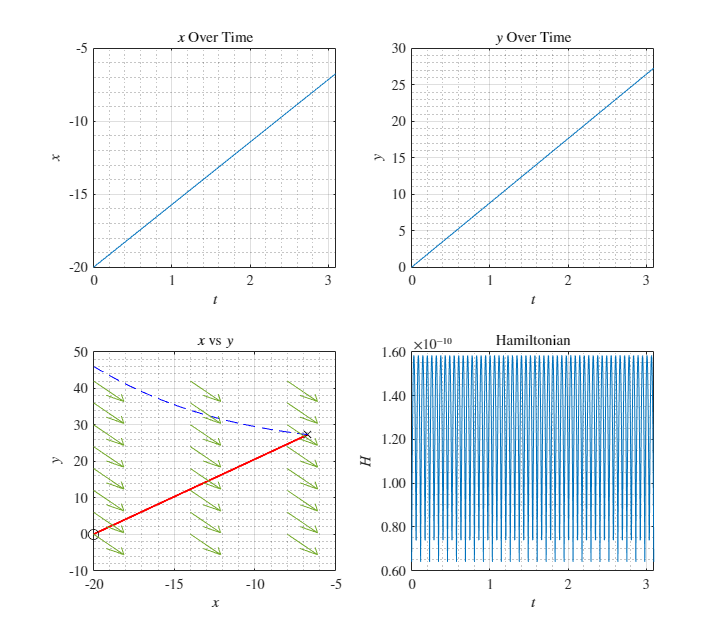

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x vs t
    subplot(2,2,1)
    plot(tspan, x_sol)
    title('$x$ Over Time')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on;
    % y vs t
    subplot(2,2,2)
    plot(tspan, y_sol)
    title('$y$ Over Time')
    xlabel('$t$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % x - y with current
    subplot(2,2,3)
    plot(x_sol, y_sol,'-r',LineWidth=1.5)
    hold on;
    plot(x_sol(1),y_sol(1),'ok',MarkerSize=7)
    plot(x_sol(end),y_sol(end),'xk',MarkerSize=7)
    plot(x_shore,y_shore, '--b')
    quiver(X,Y,U,V)
    title('$x$ vs $y$')
    xlabel('$x$')
    ylabel('$y$')
    grid on; grid minor; box on; hold off;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    ytickformat('%,.2f')
    grid on; grid minor; box on;

% saveas(fig, 'p4b.png');

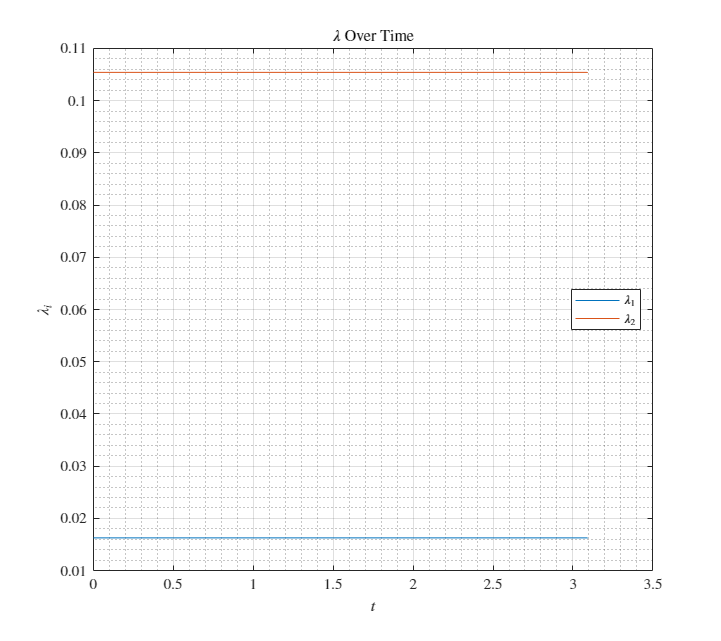

% Plot costates 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, lambda1_sol,'DisplayName','$\lambda_1$')
    hold on;
    plot(tspan, lambda2_sol,'DisplayName','$\lambda_2$')
    title('$\lambda$ Over Time')
    xlabel('$t$')
    ylabel('$\lambda_i$')
    legend('Location','best'); grid on; grid minor; box on; hold off;

% saveas(fig,'p4b_lambda.png');

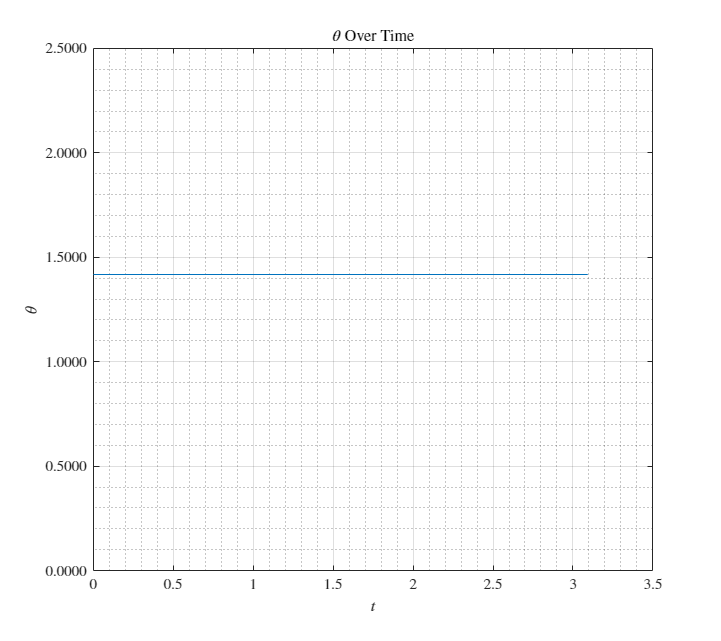

% Plot control 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, theta_sol)
    title('$\theta$ Over Time')
    xlabel('$t$')
    ylabel('$\theta$')
    ytickformat('%,.4f')
    grid on; grid minor; box on;

% saveas(fig, 'p4b_theta.png'); 

## Function

function dxdt = odefcn(t,x,V)
    dxdt = zeros(5,1); 
    theta = atan2(x(4),x(3));
    dxdt(1) = V * cos(theta) + 2; % x
    dxdt(2) = V * sin(theta) - 6; % y
    dxdt(3) = 0; % lambda1
    dxdt(4) = 0; % lambda2
    dxdt(5) = 0; % tf
    dxdt = dxdt * x(5);
end

function res = bcfcn(xa,xb,V)
    res = zeros(5,1);
    theta_f = atan2(xb(4),xb(3));
    res(1) = xa(1) + 20; % x(0)
    res(2) = xa(2);  % y(0)
    res(3) = ((-0.25 - 0.006 * xb(1)^2)*(xb(4)-2*(xb(2)-35.5) ...
        + xb(3) - 2*(xb(1)+15))); % -l = Psi_x
    res(4) = 25 - 0.25*xb(1) - 0.002*xb(1)^3 - xb(2); % Psi(t_f)
    res(5) = (-1 + xb(3) * (V*cos(theta_f)+2) ...
        + xb(4)*(V*sin(theta_f)-6)) * xb(5); % H(t_f)
end